## ADJUSTMENT THEORY I

### Exercise 9: Adjustment Calculation - part IV  

#### Author:  Group G

#### Date: 19.01.2022

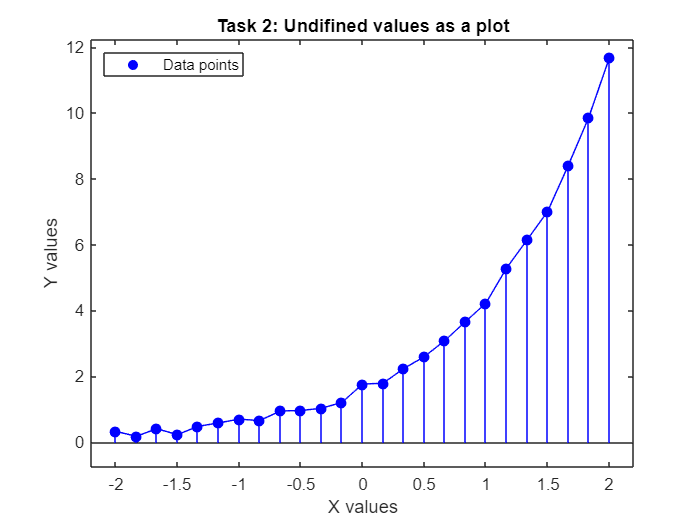

clc;
clear all;
close all;
format default;

%--------------------------------------------------------------------------
%   Task 2 
%--------------------------------------------------------------------------
%--------------------------------------------------------------------------
%   Observations and initial values for the unknowns
%--------------------------------------------------------------------------
%Load data
data = load("Exercise9Task2.txt");

%Plot the data
x = data(:,1);
y = data(:,2);

plot(x,y,'-b')
hold on;
scatter(x,y,'b','filled')
Buffer = 5; % in pecrent
xlim([min(x)-(max(x)- min(x)) * Buffer / 100, ...
    max(x)+(max(x)- min(x)) * Buffer / 100]);
ylim([-min(y)-(max(y)- min(y)) * Buffer / 100, ...
    max(y)+(max(y)- min(y)) * Buffer / 100]);
stem(x,y,'b')
hold off;
xlabel('X values');
ylabel('Y values');
title('Task 2: Undifined values as a plot');
legend_cell = {'','Data points'};
legend(legend_cell,'Location','northwest')

***Appropriate functional model:*** 


$$Y=ae^{{\mathrm{bx}}_i } +c$$
  
$$\to \varphi_i \;\;\;$$
   

***Discription of the data:*** 

Our observation are the undifined Y value from the data Table.

We also have an error-free observation of the density of the undifined X value.

The unknow parameter we want the calculate are a, b and c.

***Linear or non-linear?***

To determine if the problem is a linear or non-linear adjustment problem we have to look at the unkowns we want to calculate. Only they show if we need to solve the problem linear or non-linear. The other variables dosen't matter for this classification, because they are not the unkowns we want to determine. 

In this case we see that our unknow $b$ dosen't scale linear in the equation $\ldotp \ldotp \ldotp e^{{\mathrm{bx}}_i } \ldotp \ldotp \ldotp$, but exponential. That indicates that we need a non-linear solution to solve the problem. Even though the other to unknown parameters $a$ and $c$ scale linear, the adjustment problem is still non-linear because at least one paramter does not scale linear.

%Error-free values
%x = x;

%Vector of observations
L = y;

%Number of observations
no_n = length(y);

%Initial values for the unknowns  
a = 1.7637;
b = log(2);
c = 0;

%Vector of initial values for the unknowns
X_0 = [a,b,c]';

%Number of unknowns
no_u = length(X_0);

%Redundancy
r = no_n - no_u;

%--------------------------------------------------------------------------
%  Stochastic model
%--------------------------------------------------------------------------
%VC Matrix of the observations
s_y = 0.15;  %[m]
S_LL = eye(no_n) * s_y^2;

%Theoretical standard deviation
sigma_0 = 1;     %a priori

%Cofactor matrix of the observations
Q_LL = (1/sigma_0^2) * S_LL;

%Weight matrix
P = inv(Q_LL);

%--------------------------------------------------------------------------
%  Adjustment
%--------------------------------------------------------------------------
%break-off conditions
epsilon = 10^-8;
delta = 10^-12;
max_x_hat = inf;
Check2 = inf;

%Number of iterations
iteration = 0;

while max_x_hat > epsilon || Check2 > delta
    
     %Observations as functions of the approximations for the unknowns
     L_0 = a*exp(b*x) + c;
     
     %Vector of reduced observations
     l = L - L_0;
    
     %Design matrix with the elements from the Jacobian matrix J
     A(:,1) = exp(b*x);
     A(:,2) = a*x .* exp(b*x);
     A(:,3) = 1;
    
     %Normal matrix
     N = A' * P * A;
     
     %Vector of right hand side of normal equations
     n =  A' * P * l;
    
     %Inversion of normal matrix / Cofactor matrix of the unknowns
     Q_xx = inv(N);
    
     %Solution of the normal equations
     x_hat = Q_xx * n;
       
     %Update
     X_0 = X_0 + x_hat;

     a = X_0(1);
     b = X_0(2);
     c = X_0(3);
    
     %Check 1
     max_x_hat = max(abs(x_hat));
     
     %Vector of residuals
     v = A*x_hat - l;
 
     %Vector of adjusted observations
     L_hat = L+v;
    
     %Objective function
     vTPv = v'*P*v;
    
     %Functional relationships without the observations
     Psy_X_hat = a*exp(b*x) + c;

     %Check 2
     Check2 = max(abs(L_hat - Psy_X_hat));
    
     %Update number of iterations
     iteration = iteration+1;
  
end

if Check2<=delta
    disp('Everything is fine!')
else
    disp('Something is wrong.')
end

Everything is fine!


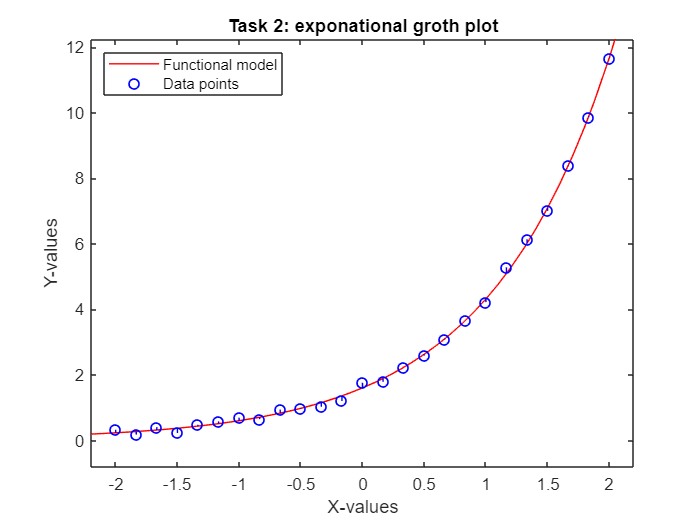

%Empirical reference standard deviation
s_0 = sqrt(vTPv/r);

%VC matrix of adjusted unknowns
S_XX_hat = s_0^2 * Q_xx;

%Standard deviation of the adjusted unknowns
s_X = sqrt(diag(S_XX_hat));

%Cofactor matrix of adjusted observations
Q_LL_hat = A * Q_xx * A';

%VC matrix of adjusted observations
S_LL_hat = s_0^2 * Q_LL_hat;

%Standard deviation of the adjusted observations
s_L_hat = sqrt(diag(S_LL_hat));

%Cofactor matrix of the residuals
Q_vv = Q_LL - Q_LL_hat;

%VC matrix of residuals
S_vv = s_0^2 * Q_vv;

%Standard deviation of the residuals
s_v = sqrt(diag(S_vv));

%--------------------------------------------------------------------------
%  Plot
%--------------------------------------------------------------------------

%Residual Plot

Fu = @(x) a*exp(b*x) + c;
fplot(Fu,'red')
xlabel('X-values');
ylabel('Y-values');
title('Task 2: exponational groth plot');
Buffer = 5; % in pecrent
xlim([min(x)-(max(x)- min(x)) * Buffer / 100, ...
    max(x)+(max(x)- min(x)) * Buffer / 100]);
ylim([-min(L_0)-(max(L_0)- min(L_0)) * Buffer / 100, ...
    max(L_0)+(max(L_0)- min(L_0)) * Buffer / 100]);
hold on;
plot(x,Psy_X_hat-v,'bo','linewidth',1);
for i = 1:no_n

    plot([x(i),x(i)],[Psy_X_hat(i),Psy_X_hat(i)-v(i)],'blue')

end
legend_cell = {'Functional model','Data points'};
legend(legend_cell,'Location','northwest')
hold off;

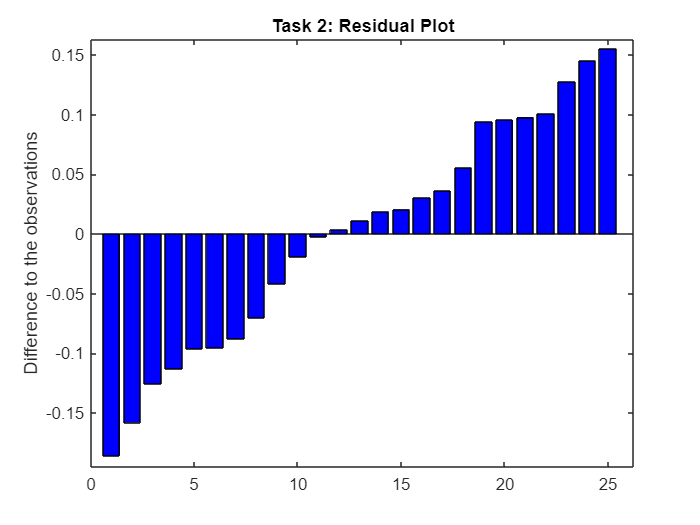

bar(sort(v),'blue')

Buffer = 5; % in pecrent
xlim([0 + 0 * Buffer / 100, ...
    length(v) + length(v) * Buffer / 100]);
ylim([min(sort(v)) + min(sort(v)) * Buffer / 100, ...
    max(sort(v)) + max(sort(v)) * Buffer / 100]);
title('Task 2: Residual Plot');
ylabel('Difference to the observations');
hold off;

The Residuals look fine. Looks like there is no blunder in the data. The resudials are also no well normaly, but instead more linearly distributed. But we whould need more residuals to define the distribution more accurate.

%Tables
table(x,L,L_hat,s_L_hat,v,s_v,'VariableNames',...
{'X-Value','L (Y)'...
'L_hat',...
's_L_hat',...
'v',...
's_v'})

ans = 25×6 table
    X-Value      L (Y)      L_hat     s_L_hat         v           s_v   
    ________    _______    _______    ________    __________    ________

          -2    0.33071     0.2356    0.037429     -0.095111    0.094325
     -1.8333    0.17904    0.27463    0.036055      0.095589    0.094859
     -1.6667    0.40871    0.32069    0.034571      -0.08802    0.095409
        -1.5    0.22969    0.37511    0.032989       0.14542    0.095968
     -1.3333     0.4808    0.43938     0.03133     -0.041419    0.096522
     -1.1667    0.58511    0.51522    0.029635     -0.069885    0.097056
          -1    0.70061    0.60484     0.02796     -0.095772    0.097552
    -0.83333     0.6549    0.71064    0.026393      0.055741    0.097987
    -0.66667    0.94867    0.83557    0.025051  

table([1.7637,log(2),0]',X_0,s_X,'VariableNames',...
{'X',...
'X_hat',...
's_X_hat'},...
'RowNames',{'a','b','c'})

ans = 3×3 table
            X        X_hat      s_X_hat 
         _______    ________    ________

    a     1.7637      1.5861    0.051961
    b    0.69315     0.99744    0.016405
    c          0    0.019836    0.048756
